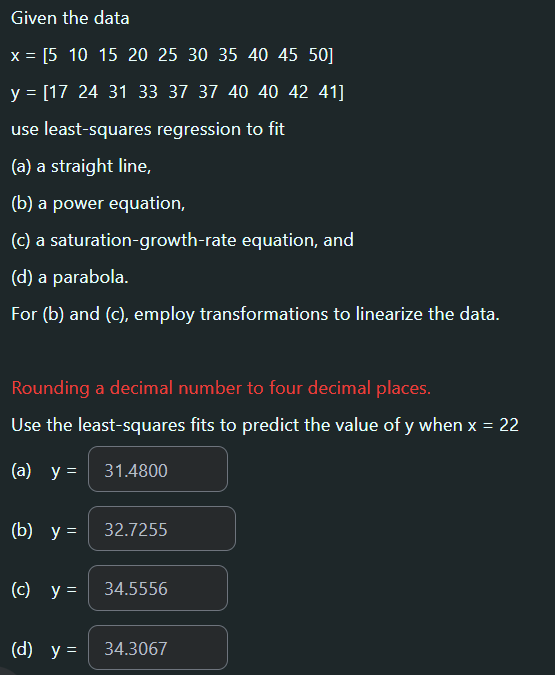

x = [5  10  15  20  25  30  35  40  45  50];
y = [17  24  31  33  37  37  40  40  42  41];

p_a = polyfit(x,y,1);
xx = 5 : 0.5 : 50;
yy = polyval(p_a,xx);

%-------straight_line--------%
xtest = 22;
predict_straight_line = polyval(p_a,xtest)

predict_straight_line = 31.4800


%-------expo--------%
new_y = log(y);
p_expo = polyfit(x,new_y,1);
alpha = exp(p_expo(2));
beta = p_expo(1);

xx = 5 : 0.5 : 50;
yy = alpha * exp(beta * xx);

predict_expo = alpha * exp(beta * xtest)

predict_expo = 30.2041

%-------power--------%
new_x = log10(x);
new_y = log10(y);
p_b = polyfit(new_x,new_y,1);
alpha = 10^p_b(2);
beta = p_b(1);

xx = 5 : 0.5 : 50;
yy = alpha * xx.^beta;

predict_power = alpha * xtest.^beta

predict_power = 32.7255

%-------growth--------%
new_x = 1./x;
new_y = 1./y;
p_growth = polyfit(new_x,new_y,1);
alpha = 1/p_growth(2);
beta = alpha*p_growth(1);

xx = 5 : 0.5 : 50;
yy = alpha * (xx ./ (beta + xx));

predict_growth = alpha * (xtest ./ (beta + xtest))

predict_growth = 34.5556

%-------parabola--------%
p_d = polyfit(x,y,2);
predict_parabola = polyval(p_d,xtest)

predict_parabola = 34.3067